clc; clear all;
syms z q0 q1 q2 s0;

# Discretización de la planta

%Modelo matemático del sistema para el segundo tanque:
K=0.23;
B=0.00171;
R=5.45;
L=3.8;
J=0.0019;
Ka=K;

numP=[K]

numP = 0.2300

denP=[L*J (R*J + L*B) (R*B+K*Ka)]

denP =     0.0072    0.0169    0.0622


Planta=tf(numP,denP)


Planta =
 
                0.23
  ---------------------------------
  0.00722 s^2 + 0.01685 s + 0.06222
 
Continuous-time transfer function.



%Definición del período de muestreo (50 veces más rápido que el tiempo de establecimiento de la planta)
tsla=0.5      %Tiempo de establecimiento lazo abierto

tsla = 0.5000

tm=(tsla)/50   %50 veces más rápido

tm = 0.0100


%Nuestro minimo tiempo de muestreo es 0.4 y lo haremos mejor:
% tm=0.3

%Discretización de la planta mediante retenedor de orden cero (Zero order hold)
PDisc=c2d(Planta,tm,'zoh')


PDisc =
 
   0.00158 z + 0.001568
  ----------------------
  z^2 - 1.976 z + 0.9769
 
Sample time: 0.01 seconds
Discrete-time transfer function.


zpk(PDisc)


ans =
 
   0.0015804 (z+0.9922)
  -----------------------
  (z^2 - 1.976z + 0.9769)
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.


%Comparación plantas (Discreta vs Continua)
tini=0

tini = 0

tfin=6

tfin = 6

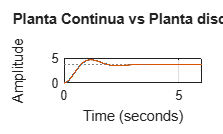

step(PDisc,tini:tm:tfin);
hold("on")
step(Planta,tini:tm:tfin);
title('Planta Continua vs Planta discreta')
grid on;

%Reescribimos la TF en potencias negativas
[numDisc,denDisc] = tfdata(PDisc, 'v')

numDisc =          0    0.0016    0.0016


denDisc =     1.0000   -1.9761    0.9769


Kdisc1=numDisc(2)

Kdisc1 = 0.0016

Kdisc2=numDisc(3)

Kdisc2 = 0.0016

bdisc1=denDisc(2)

bdisc1 = -1.9761

bdisc2=denDisc(3)

bdisc2 = 0.9769



%Para escalón se necesita 1 integrador
Controlador=(q0 + (q1*z^-1) + (q2*z^-2)) / ((1 - 1*z^-1)*(1-s0*z^-1))

$$Controlador = \frac{q_{0}+\frac{q_{1}}{z}+\frac{q_{2}}{z^{2}}}{\left(\frac{s_{0}}{z}-1\right)\,\left(\frac{1}{z}-1\right)}$$


%Se convierte a potencias positivas
Controlador=(q0*z^2 + q1*z + q2)/((z-1)*(z-s0))

$$Controlador = -\frac{q_{0}\,z^{2}+q_{1}\,z+q_{2}}{\left(s_{0}-z\right)\,\left(z-1\right)}$$


numC=(q0*z^2 + q1*z + q2)

$$numC = q_{0}\,z^{2}+q_{1}\,z+q_{2}$$

denC=((z-1)*(z-s0))

$$denC = -\left(s_{0}-z\right)\,\left(z-1\right)$$

numP=Kdisc1*z + Kdisc2

$$numP = \frac{7288139627108223\,z}{4611686018427387904}+\frac{225989107360267}{144115188075855872}$$

denP=(z^2 + bdisc1*z + bdisc2)

$$denP = z^{2}-\frac{4449728670813427\,z}{2251799813685248}+\frac{2199846770978429}{2251799813685248}$$


PC=numC*numP + denC*denP

$$PC = \left(\frac{7288139627108223\,z}{4611686018427387904}+\frac{225989107360267}{144115188075855872}\right)\,\left(q_{0}\,z^{2}+q_{1}\,z+q_{2}\right)-\left(s_{0}-z\right)\,\left(z-1\right)\,\left(z^{2}-\frac{4449728670813427\,z}{2251799813685248}+\frac{2199846770978429}{2251799813685248}\right)$$

PC=collect(PC)

$$PC = z^{4}+\left(\frac{7288139627108223\,q_{0}}{4611686018427387904}-s_{0}-\frac{6701528484498675}{2251799813685248}\right)\,z^{3}+\left(\frac{225989107360267\,q_{0}}{144115188075855872}+\frac{7288139627108223\,q_{1}}{4611686018427387904}+\frac{6701528484498675\,s_{0}}{2251799813685248}+\frac{415598465111991}{140737488355328}\right)\,z^{2}+\left(\frac{225989107360267\,q_{1}}{144115188075855872}+\frac{7288139627108223\,q_{2}}{4611686018427387904}-\frac{415598465111991\,s_{0}}{140737488355328}-\frac{2199846770978429}{2251799813685248}\right)\,z+\frac{225989107360267\,q_{2}}{144115188075855872}+\frac{2199846770978429\,s_{0}}{2251799813685248}$$

# Se diseña el polinomio deseado

zeta=0.7

zeta = 0.7000

ts=0.5

ts = 0.5000

wn=4/(zeta*ts)

wn = 11.4286

wd=wn*sqrt(1 - zeta^2)

wd = 8.1616

PD=vpa(collect((z^2 - z*(2*cos(wd*tm)*exp(-zeta*wn*tm)) + exp(-2*zeta*wn*tm))^2),3)

$$PD = z^{4}-3.68\,z^{3}+5.09\,z^{2}-3.14\,z+0.726$$

# Se despejan las ganancias

PCcoeffs=coeffs(PC,'z','All')

$$PCcoeffs = \left(\begin{array}{ccccc} 1 & \frac{7288139627108223\,q_{0}}{4611686018427387904}-s_{0}-\frac{6701528484498675}{2251799813685248} & \frac{225989107360267\,q_{0}}{144115188075855872}+\frac{7288139627108223\,q_{1}}{4611686018427387904}+\frac{6701528484498675\,s_{0}}{2251799813685248}+\frac{415598465111991}{140737488355328} & \frac{225989107360267\,q_{1}}{144115188075855872}+\frac{7288139627108223\,q_{2}}{4611686018427387904}-\frac{415598465111991\,s_{0}}{140737488355328}-\frac{2199846770978429}{2251799813685248} & \frac{225989107360267\,q_{2}}{144115188075855872}+\frac{2199846770978429\,s_{0}}{2251799813685248} \end{array}\right)$$

PDcoeffs=coeffs(PD,'z',"All")

$$PDcoeffs = \left(\begin{array}{ccccc} 1 & -3.6801740403170697391033172607422 & 5.0902078197104856371879577636719 & -3.1360374508076347410678863525391 & 0.72614903707290068268775939941406 \end{array}\right)$$

eq=PCcoeffs==PDcoeffs

$$eq = \left(\begin{array}{ccccc} 1=1 & \frac{7288139627108223\,q_{0}}{4611686018427387904}-s_{0}-\frac{6701528484498675}{2251799813685248}=-3.6801740403170697391033172607422 & \frac{225989107360267\,q_{0}}{144115188075855872}+\frac{7288139627108223\,q_{1}}{4611686018427387904}+\frac{6701528484498675\,s_{0}}{2251799813685248}+\frac{415598465111991}{140737488355328}=5.0902078197104856371879577636719 & \frac{225989107360267\,q_{1}}{144115188075855872}+\frac{7288139627108223\,q_{2}}{4611686018427387904}-\frac{415598465111991\,s_{0}}{140737488355328}-\frac{2199846770978429}{2251799813685248}=-3.1360374508076347410678863525391 & \frac{225989107360267\,q_{2}}{144115188075855872}+\frac{2199846770978429\,s_{0}}{2251799813685248}=0.72614903707290068268775939941406 \end{array}\right)$$

[q0,q1,q2,s0]=solve(eq,[q0,q1,q2,s0])

$$q0 = 12.850562976538916364952089644798$$

$$q1 = -24.574114068624764135765869083595$$

$$q2 = 11.769721231367506834877247971563$$

$$s0 = 0.72440610977577939202238894168351$$

q0=double(q0)

q0 = 12.8506

q1=double(q1)

q1 = -24.5741

q2=double(q2)

q2 = 11.7697

s0=double(s0)

s0 = 0.7244